## A03 - MGc

clear all;
close all;
clc;

Using the setting of the M/M/c exercises, now consider the service generally distributed, according to the distribution given in the provided table. Consider a FCFS queue, so that the system is M/G/c : use the Pollaczek–Khinchine formula for the M/G/1 case, and the approximation provided by the Kingsman formula for c > 1. Limit the analysis up to c=4.

### Recall

In the case of $c=1$ we have to use the Pollaczek-Khinchine formula, but we notice that the Kingsman formula approximation holds also in the case of $c=1$. So we can only compute the Kingsman formula for all the possible values of $c$.


$$R \cong D + \left[ \frac{c_a^2 + c_v^2}{2} \right] E[\Theta_{M/M/c}]$$


Lmin = 1;
Lmax = 10;

L = (Lmin:(Lmax-Lmin)/50:Lmax);
c = 1:8;

k = 4;
mu = 2;

In case of *Erlang *distribution:


$$c_v = \frac{1}{\sqrt{k}}$$



$$D = \frac{k}{\mu}$$


cv = 1/sqrt(k)

cv = 0.5000

D = k / mu

D = 2

### a. Verify if the system is stable

In order to be stable, a system must have $\overline{U} < 1$, with $\overline{U} = \frac{\lambda \times D}{c} = \rho$

Ubar_fun = @(l,c) (l.*D)./c;

Ubar = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        Ubar(i,j) = Ubar_fun(L(i), c(j));
    end
end

UbarT = array2table(Ubar, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

UbarT = 51×8 table
             1       2         3        4        5         6          7         8  
            ____    ____    _______    ____    _____    _______    _______    _____

    1          2       1    0.66667     0.5      0.4    0.33333    0.28571     0.25
    1.18    2.36    1.18    0.78667    0.59    0.472    0.39333    0.33714    0.295
    1.36    2.72    1.36    0.90667    0.68    0.544    0.45333    0.38857     0.34
    1.54    3.08    1.54     1.0267    0.77    0.616    0.51333       0.44    0.385
    1.72    3.44    1.72     1.1467    0.86    0.688    0.57333    0.49143     0.43
    1.9      3.8  

Let's plot $\bar{U}$ results in an heatmap:

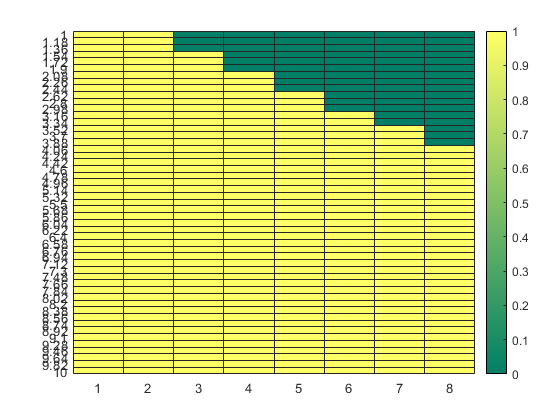

hm = heatmap(strtrim(cellstr(num2str(c'))'), ...
        strtrim(cellstr(num2str(L'))'), ...
        double(Ubar>=1), ...
        'Colormap', summer);

### b. Compute $\Theta$

$\Theta$ is the one computed for the *M/M/c *case, so we need only to recover the previous computed values and we multiply it for the coefficient of variation factor, that becames from the Kingsman formula.


$$\Theta = \frac{\frac{D}{c(1-\rho)}}{1 + (1-\rho) \left(\frac{c!}{(c\rho)^c}\right) \sum_{k=0}^{c-1} \frac{(c\rho)^k}{k!}} \cdot \left[ \frac{c_a^2 + c_v^2}{2} \right]$$


theta = @(C,p,D,k,cv) (D / (C*(1-p)) / (1 + (1-p)*(factorial(C)/((C*p)^C))*sum(((C*p).^k)./factorial(k)))) * (1+cv^2)/2;

Theta = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        if Ubar(i,j) < 1
            rho = Ubar(i,j);
            k = 0:c(j)-1;
            
            Theta(i,j) = theta(c(j), rho, D, k,cv);
        end 
    end
end

ThetaT = array2table(Theta, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

ThetaT = 51×8 table
            1    2       3          4          5            6            7            8     
            _    _    _______    _______    ________    _________    _________    __________

    1       0    0    0.55556     0.1087    0.024876    0.0056306    0.0012026    0.00023867
    1.18    0    0     1.2219    0.20916    0.050733     0.012774    0.0031018    0.00070828
    1.36    0    0     3.7003    0.38883    0.094561     0.025588    0.0068615     0.0017549
    1.54    0    0          0    0.73846     0.16694     0.047004     0.013584     0.0038086
    1.72    0    0          0     1.5816     0.28764     0.08133

**Note that, from this point on, the remaining the tasks will have the same development as for the *****M/M/c *****case.**

### c. The average response time $R$ of the system (if possible)

From the theory we know that $R = D + \Theta$ so we only need to add D to the $\Theta$

R = (Theta + D).*double(Ubar<1);
RT = array2table(R, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

RT = 51×8 table
            1    2      3         4         5         6         7         8   
            _    _    ______    ______    ______    ______    ______    ______

    1       0    0    2.5556    2.1087    2.0249    2.0056    2.0012    2.0002
    1.18    0    0    3.2219    2.2092    2.0507    2.0128    2.0031    2.0007
    1.36    0    0    5.7003    2.3888    2.0946    2.0256    2.0069    2.0018
    1.54    0    0         0    2.7385    2.1669     2.047    2.0136    2.0038
    1.72    0    0         0    3.5816    2.2876    2.0813    2.0248    2.0075
    1.9     0    0         0    7.5714    2.4996    2.13

Let's plot the response time

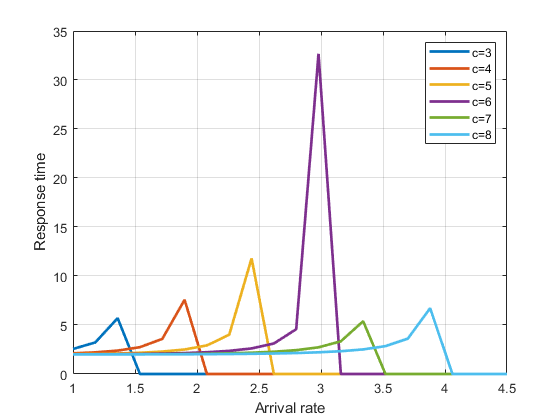

plot(L',[R(:,3),R(:,4),R(:,5),R(:,6),R(:,7),R(:,8)], 'LineWidth', 2);
xlabel("Arrival rate");
ylabel("Response time");
legend(["c=3", "c=4", "c=5", "c=6", "c=7", "c=8"]);
xlim([1, 4.5]);
grid on;
hold off;

### d. The average queue length of the system (if possible)

In order to compute$N$:


$$N = X \cdot R = \lambda \cdot R$$


N = (L'.*R).*double(Ubar<1);
NT = array2table(N, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

NT = 51×8 table
            1    2      3         4         5         6         7         8   
            _    _    ______    ______    ______    ______    ______    ______

    1       0    0    2.5556    2.1087    2.0249    2.0056    2.0012    2.0002
    1.18    0    0    3.8019    2.6068    2.4199    2.3751    2.3637    2.3608
    1.36    0    0    7.7524    3.2488    2.8486    2.7548    2.7293    2.7224
    1.54    0    0         0    4.2172    3.3371    3.1524    3.1009    3.0859
    1.72    0    0         0    6.1604    3.9347    3.5799    3.4826    3.4529
    1.9     0    0         0    14.386    4.7492    4.05

### e. The probability of having the empty system (if possible)

In order to compute $p_0$:


$$p_0 = \left[ \frac{(c\rho)^c}{c!} \frac{1}{1-\rho} + \sum_{k=0}^{c-1} \frac{(c\rho)^k}{k!} \right]^{-1}$$


p0 = @(C, p, k) ( (C*p)^C/factorial(C)/(1-p) + sum(((C*p).^k)./factorial(k)) )^-1;

P0 = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        if Ubar(i,j) < 1
            rho = Ubar(i,j);
            k = 0:c(j)-1;
            
            P0(i,j) = p0(c(j), rho, k);
        end 
    end
end

P0T = array2table(P0, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

P0T = 51×8 table
            1    2       3            4            5             6             7             8     
            _    _    ________    _________    __________    __________    __________    __________

    1       0    0     0.11111      0.13043       0.13433       0.13514        0.1353       0.13533
    1.18    0    0    0.060925     0.087047      0.092735      0.094041      0.094339      0.094404
    1.36    0    0    0.023066     0.055865      0.063393       0.06526      0.065727      0.065841
    1.54    0    0           0     0.033338       0.04263      0.045068      0.045725        0.0459
    1.72    0    0       